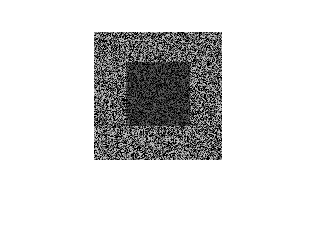

left = imread("input\pair0-L.png");
imshow(left);

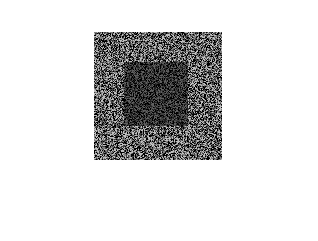

right = imread("input\pair0-R.png");
imshow(right);

% left = [1, 1, 2, 2, 1, 1];
% right =[1, 2, 2, 1 ,1 ,1];
% rows = size(left,1);
% columns = size(left,2);
%  wsize = 7;
%  D = zeros(rows,columns);
%     
%     for tmpr = 1:rows
%         for tmpc = 1:columns
%             arr = zeros(1,columns);
%             for samplec=1:columns
%                svalue =0 ; 
%                 for ir = 0: (wsize-1)
%                   for  ic = 0 : (wsize-1)
%                      if(tmpr-floor(wsize/2)+ir >=1  && tmpr-floor(wsize/2)+ir <= rows && ...
%                         tmpc-floor(wsize/2)+ ic >= 1 && tmpc-floor(wsize/2)+ ic <= columns  &&...
%                         samplec-floor(wsize/2)+ic >=1  && samplec-floor(wsize/2)+ic <= columns)                     
%                      tvalue = right(tmpr- floor(wsize/2) + ir , tmpc - floor(wsize/2) +ic);
%                      ivalue = left(tmpr - floor(wsize/2) + ir , samplec - floor(wsize/2) + ic);
%                      svalue = svalue + (tvalue-ivalue)^2;
%                      end
%                    end
%                 end
%                 arr(1,samplec) = svalue;
%             end
%             [minv, mini] = min(arr);     
%             D(tmpr, tmpc) = tmpc - mini;
%         end
%     end
%     disp(D);
    

tic
D_L = disparity_ssd(left,right,3); 
toc

Elapsed time is 24.141156 seconds.


% D_R = disparity_ssd(right, left);
               

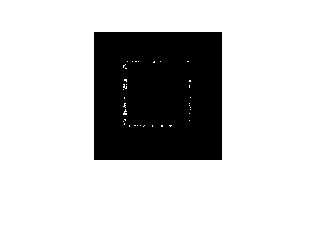

% 
% D_L(D_L ~= -2)=0;
% D_L(D_L == -2) = 2; 
% imagesc(D_L);
imshow(D_L);

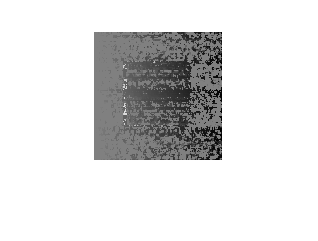

imshow(D_L,[-128, 128]);

% imshow(D_R,[-128,128]);


